% setup
clear all;
close all;
s = RandStream('mt19937ar','Seed',0); % to reproduce fig from manuscript
RandStream.setGlobalStream(s);
fs = 14; % font size for plots

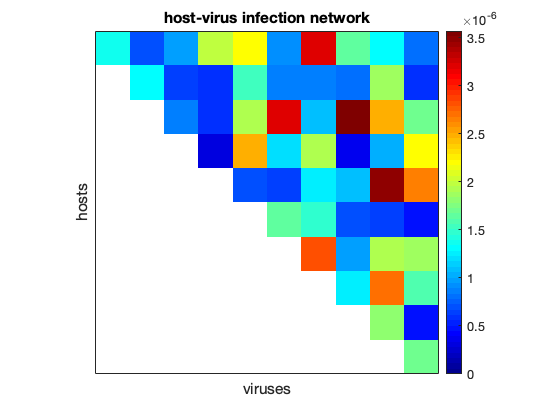

% generate a parameter set for synthetic community
nH = 10;
nV = 10;
M = triu(ones(nH,nV)); % for now, use an easy-to-visualize network
params = generate_parameters(nH,nV,M);
[K,r,m,M,phi,beta] = params{:};
Mtilde = M.*phi.*beta; % the weighted virus-host infection network

% plot
figure();
plot_network(Mtilde,0,fs);
title('host-virus infection network');

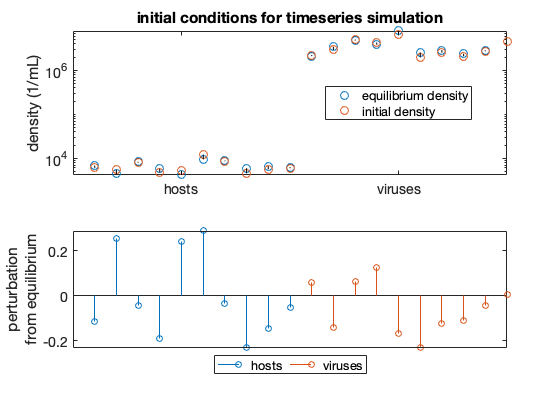

% set initial conditions
xEq = equilibrium(params); % calculate equilibrium densities
delta = 0.3; % randomly perturb equilibrium densities
x0 = xEq.*((1-delta) + 2*delta*rand(nV+nH,1));

% plot
figure();
subplot(2,1,1);
semilogy(xEq,'o','MarkerSize',8);
hold on;
semilogy(x0,'o','MarkerSize',8);
for i = 1:length(xEq)
    semilogy([i i],[xEq(i) x0(i)],'k-','HandleVisibility','off')
end
set(gca,'FontSize',fs);
hold off;
legend({'equilibrium density','initial density'},'Location','best');
set(gca,'XTick',[nH/2 nH+nV/2],'XTickLabel',{'hosts','viruses'});
ylabel('density (1/mL)');
title('initial conditions for timeseries simulation');

subplot(2,1,2);
tmpdat = x0./xEq-1;
stem(1:nH,tmpdat(1:nH));
hold on;
stem(nH+1:nH+nV,tmpdat(nH+1:end));
hold off;
legend({'hosts','viruses'},'Location','southoutside','Orientation','horizontal')
ylabel(sprintf('perturbation\nfrom equilibrium'));
set(gca,'XTick',[]);
set(gca,'FontSize',14);

clear i;



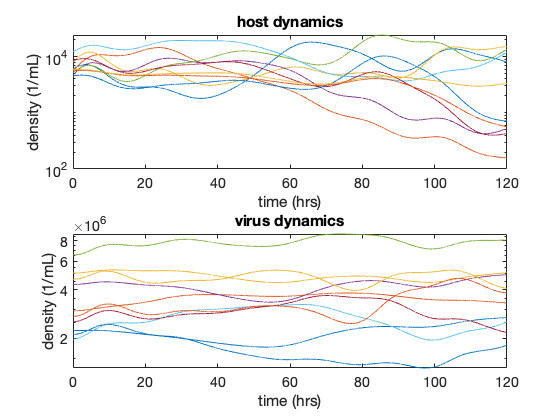

% simulate the timeseries
tfinal = 120; % units = hours
dt = 0.01;
tVector = dt:dt:tfinal;
[t,H,V] = simulate_dynamics(params,x0,tVector);

% plot
figure();
subplot(2,1,1);
semilogy(t,H);
xlim([t(1) t(end)]);
title('host dynamics');
xlabel('time (hrs)');
ylabel('density (1/mL)');
set(gca,'FontSize',fs);
subplot(2,1,2);
semilogy(t,V);
xlim([t(1) t(end)]);
xlabel('time (hrs)');
ylabel('density (1/mL)');
title('virus dynamics');
set(gca,'FontSize',fs);

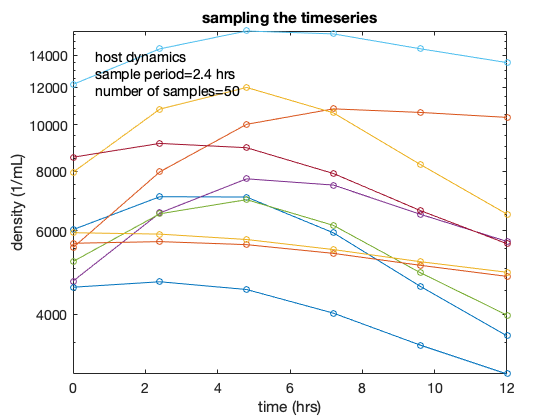

% sample the timeseries
nMeas = 500; % number of samples to take
ds = floor(length(t)/nMeas);
dt_sample = ds*dt; % how often are timeseries sampled (units = hours)
sampleID = 1:ds:length(t);
tsample = t(sampleID);
Hsample = H(sampleID,:);
Vsample = V(sampleID,:);

% plot
tmpID = find(tsample>=dt_sample*5,1);
tmpstr = sprintf('host dynamics\nsample period=%.2g hrs\nnumber of samples=%d',dt_sample,nMeas);
figure();
semilogy(tsample(1:tmpID),Hsample(1:tmpID,:),'o-');
xlim([tsample(1) tsample(tmpID)]);
title('sampling the timeseries');
xlabel('time (hrs)');
ylabel('density (1/mL)');
text(0.05,0.95,tmpstr,'Units','Normalized','FontSize',fs,'VerticalAlignment','top');
set(gca,'FontSize',fs);

clear tmpID tmpstr;

% infer the virus-host infection network
lambda = 10; % tune sparsity penalty (higher lambda -> more sparse M_hat)
[Mtilde_hat, m_hat, h, W] = infer_network(tsample,Hsample,Vsample,lambda);

 
Calling SDPT3 4.0: 821 variables, 212 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 212
 dim. of socp   var  = 701,   num. of socp blk  = 101
 dim. of linear var  = 120
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.2e+02|7.0e+05|3.8e+07| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.989|1.3e+00|7.5e+03|5.0e+06|-3.990476e-03 -4.702131e+06| 0:0:00| chol  1  1 
 2|0.967|0.988|4.4e-02|9.2e+01|7.6e+04|-1.842217e-03 -7.453073e+04| 0:0:00| chol  1  1 
 3|0.344|0.922|2.9e-02|7.2e+00|

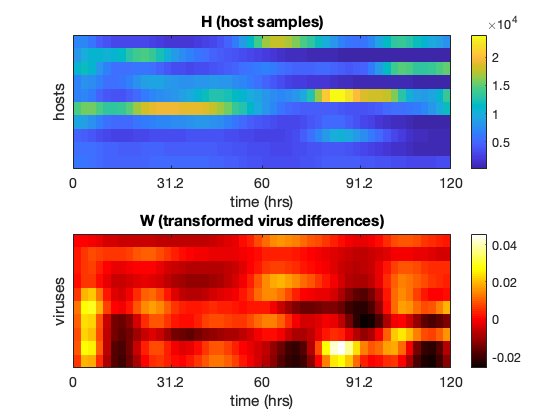

relerr = inference_error(Mtilde_hat,Mtilde);

% plot
figure();
subplot(2,1,1);
plot_timeseries(tsample,h,'host',fs);
subplot(2,1,2);
plot_timeseries(tsample,W,'virus',fs);

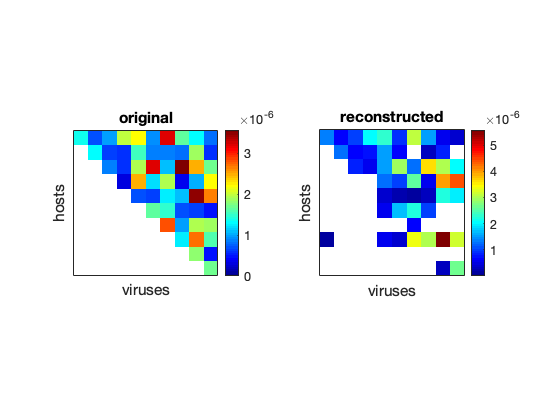


zero_thresh = 1e-7; % for visualization; show very small numbers as "zero"
figure();
subplot(1,2,1);
plot_network(Mtilde,0,fs);
title('original');
subplot(1,2,2);
plot_network(Mtilde_hat,zero_thresh,fs);
title('reconstructed');

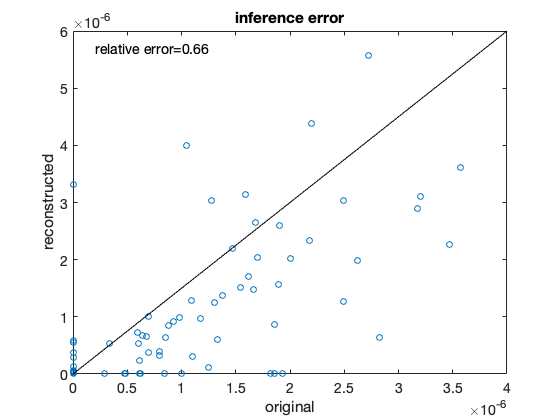


figure();
plot(Mtilde(:),Mtilde_hat(:),'o');
plot_one2one();
xlabel('original');
ylabel('reconstructed');
set(gca,'FontSize',fs);
text(0.05,0.95,sprintf('relative error=%.2g',relerr),'Units','Normalized','FontSize',fs);
title('inference error')

% generate manuscript figure
fprintf('manuscript figure');

manuscript figure

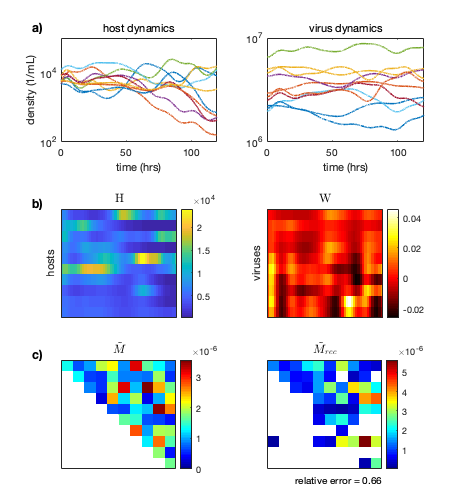

plot_recons(t,H,V,h,W,Mtilde,Mtilde_hat);
print('mod3_inference','-dpng');